# EXAMEN CALCUL NUMERIC 5 IUNIE 2024

# SET 1

# Bugnar Andreea - gr. 231

# PROBLEMA 1

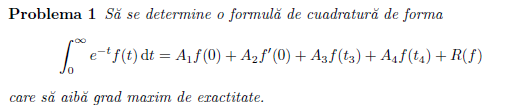


$$\begin{array}{l}
\textrm{Se}\;\textrm{observă}\;\textrm{că}\;\textrm{avem}\;6\;\textrm{necunoscute}\;A_1 ,\;A_2 ,\;A_3 ,\;A_4 ,t_3 ,\;t_4 \ldotp \;\\
\textrm{Se}\;\textrm{îndeplinește}\;R\left(f\right)=0\;\textrm{pentru}\;\textrm{orice}\;\textrm{polinom}\;\textrm{cu}\;\textrm{grad}\;\textrm{cel}\;\textrm{mult}\;5\\
\;\left(=n-1,\textrm{unde}\;n-\textrm{numărul}\;\textrm{de}\;\textrm{necunoscute}\right)\\
R\left(f\right)=\int_0^{\infty } e^{-t} f\left(t\right)+A_1 f\left(0\right)+A_2 f^{\prime } \left(0\right)+A_3 f\left(t_3 \right)+A_4 f\left(t_4 \right)\ldotp \;\\
\textrm{Înlocuim}\;\textrm{succesiv}\;f\left(t\right)\;\textrm{cu}\;\textrm{fiecare}\;\textrm{dintre}\;\textrm{polinoamele}\;\textrm{monice}\;\left(1,\;t,t^2 ,t^3 ,t^4 ,t^5 \;\right)\;\;\textrm{și}\;\textrm{obținem}\;\textrm{un}\;\textrm{sistem}\;\textrm{din}\;\textrm{care}\;\\
\textrm{scoatem}\;\textrm{cele}\;6\;\textrm{necunoscute}\ldotp \textrm{Următoarea}\;\textrm{bucată}\;\textrm{de}\;\textrm{cod}\;\textrm{identifică}\;\textrm{acest}\;\textrm{sistem}\;\textrm{și}\;\textrm{îl}\;\textrm{rezolv}ă:
\end{array}$$


syms xi a1 a2 a3 a4 t3 t4 K Rest u
ec = sym(zeros(6, 1));
for k=1:6
    ec(k) = RR(@(t) t^(k-1), a1, a2, a3, a4, t3, t4) == 0;
end
ec

$$ec = \left(\begin{array}{c} 1-a_{3}-a_{4}-a_{1}=0\\ 1-a_{3}\,t_{3}-a_{4}\,t_{4}-a_{2}=0\\ -a_{3}\,{t_{3}}^{2}-a_{4}\,{t_{4}}^{2}+2=0\\ -a_{3}\,{t_{3}}^{3}-a_{4}\,{t_{4}}^{3}+6=0\\ -a_{3}\,{t_{3}}^{4}-a_{4}\,{t_{4}}^{4}+24=0\\ -a_{3}\,{t_{3}}^{5}-a_{4}\,{t_{4}}^{5}+120=0 \end{array}\right)$$


[a1, a2, a3, a4, t3, t4] = solve(ec, [a1, a2, a3, a4, t3, t4]);


$$\mathrm{Observăm}\;\mathrm{că}\;\mathrm{elementele}\;\mathrm{din}\;a_{3\;} \mathrm{și}\;a_{4\;} \mathrm{sunt}\;\mathrm{opuse},\;\mathrm{la}\;\mathrm{fel}\;\mathrm{ca}\;\mathrm{și}\;t_3 \;\mathrm{și}\;t_4 \ldotp$$



$$\begin{array}{l}
\mathrm{Deci},\mathrm{deși}\;\mathrm{aceștia}\;\mathrm{par}\;\mathrm{diferiți},\mathrm{simetria}\;\mathrm{lor}\;\mathrm{indică}\;\mathrm{faptul}\;\mathrm{că}\;\mathrm{ele}\;\mathrm{contribuie}\;\mathrm{în}\;\mathrm{mod}\;\mathrm{egal}\;\mathrm{la}\;\mathrm{formula}\;\mathrm{de}\;\mathrm{cuadratură},\\
\mathrm{rezultând}\;\mathrm{într}-o\;\mathrm{singură}\;\mathrm{soluție}\;\mathrm{efectivă}\ldotp 
\end{array}$$



$$\begin{array}{l}
\mathrm{Încercăm}\;\mathrm{să}\;\mathrm{verificăm}\;\mathrm{dacă}\;\mathrm{gradul}\;\mathrm{nu}\;\mathrm{este}\;\mathrm{de}\;\mathrm{fapt}>5\;\mathrm{prin}\;\mathrm{folosirea}\;\mathrm{următorului}\;\mathrm{polinom}\;\mathrm{monic}\;t^6 \ldotp \mathrm{Integrala}\\
\int_0^{\infty } e^{-t} t^{6\;} \mathrm{dt}\;\mathrm{ar}\;\mathrm{trebui}\;\mathrm{să}\;\mathrm{fie}\;\mathrm{egală}\;\mathrm{cu}\;\Gamma \left(e_7 \right)\ldotp \mathrm{În}\;\mathrm{continuare}\;\mathrm{se}\;\mathrm{efectuează}\;\mathrm{această}\;\mathrm{verificare}\ldotp 
\end{array}$$


eval(a1(1)*(0)^6 + a2(1)*6*(0)^5 + a3(1)*t3(1)^6 + a4(1)*t4(1)^6) ~= factorial(6)

ans = logical
   1



$$\mathrm{Obținem}\;\mathrm{un}\;\mathrm{rezultat}\;\mathrm{pozitiv},\;\mathrm{ele}\;\mathrm{sunt}\;\mathrm{diferite},\mathrm{ceea}\;\mathrm{ce}\;\mathrm{înseamnă}\;\mathrm{că}\;\mathrm{gradul}\;\mathrm{de}\;\mathrm{exactitate}\;\mathrm{este},\mathrm{într}-\mathrm{adevăr},5\ldotp$$



$$\begin{array}{l}
\textrm{Continuăm}\;\textrm{cu}\;\textrm{aflarea}\;\textrm{restului}\;\textrm{pentru}\;\textrm{cuadratura}\;\textrm{dată}\ldotp \textrm{Se}\;\textrm{va}\;\textrm{folosi}\;\textrm{nucleul}\;\textrm{lui}\;\textrm{Peano}\;\mathrm{cu}\;\mathrm{formula}\;\\
K\left(t\right)=\frac{1}{d!}R_x \left\lbrack {\left(x-t\right)}_+^d \right\rbrack 
\end{array}$$


syms u f(x) xi

g = @(x)piecewise(x >= u, (x - u)^5 / factorial(5), 0);

K = simplify(RR(g, a1(1), a2(1), a3(1), a4(1), t3(1), t4(1)))

$$K = \left\{ \begin{array}{cl} {\mathrm{e}}^{-u}+\frac{{\left(u-2\right)}^{5}}{320}+\frac{{\left(u-6\right)}^{5}}{8640} & \text{ if }u\in \left[0,2\right]\\ {\mathrm{e}}^{-u}+\frac{{\left(u-6\right)}^{5}}{8640} & \text{ if }u\in \left[0,6\right]\\ {\mathrm{e}}^{-u} & \text{ if }0\leq u\\ 0 & \text{ if }u<0\\ \frac{u^{4}}{144} & \text{ if }u\leq 0\\ 0 & \text{ if }u\notin \mathbb{R} \end{array}\right.$$

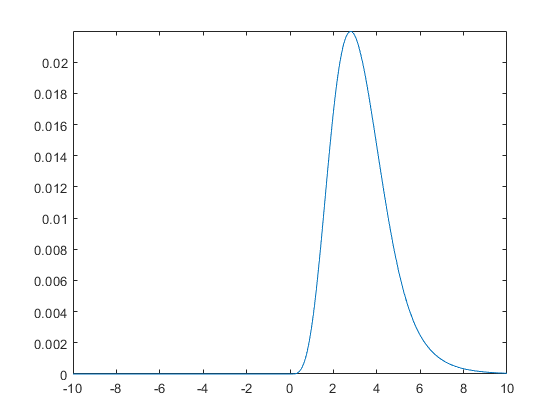

fplot(K,[-10,10])


$$\begin{array}{l}
S-a\;\mathrm{obținut}\;\mathrm{sistemul}\;\mathrm{corespunzător}\;\mathrm{nucleului}\;\mathrm{lui}\;\mathrm{Peano}\ldotp \mathrm{Vrem}\;\mathrm{să}\;\mathrm{verificăm}\;\mathrm{dacă}\;\mathrm{acesta}\;\mathrm{are}\;\mathrm{semn}\;\mathrm{constant}\;\mathrm{sau}\;\mathrm{variabil}\\
\mathrm{și}\;\mathrm{pentru}\;\mathrm{asta}\;\mathrm{am}\;\mathrm{realizat}\;\mathrm{graficul}\;\mathrm{din}\;\mathrm{care}\;\mathrm{se}\;\mathrm{observă}\;\mathrm{că}\;\mathrm{semnul}\;\mathrm{rămâne}\;\mathrm{constant}\ldotp \mathrm{Astfel},\mathrm{putem}\;\mathrm{aplica}\;\mathrm{corolarul}\;\mathrm{de}\;\mathrm{la}\;\\
\mathrm{teorema}\;\mathrm{lui}\;\mathrm{Peano}\;\mathrm{care}\;\mathrm{spune}\;\mathrm{că}\;\mathrm{Rf}\left(x\right)=\frac{f^{\left(d+1\right)} \left(\xi \right)}{\left(d+1\right)!}R\left(e_{d+1} \right)\;\mathrm{unde}\;d-\mathrm{gradul}\;\mathrm{de}\;\mathrm{exactitate}\ldotp 
\end{array}$$


Rest = 1 / factorial(6) * simplify(RR(@(x) x^6, a1(1), a2(1), a3(1), a4(1), t3(1), ...
    t4(1))) * subs(diff(f(x), x, 6), x, xi)

$$Rest = \frac{\frac{\partial^{6}}{\partial \xi^{6}}f\left(\xi \right)}{15}$$

# PROBLEMA 2

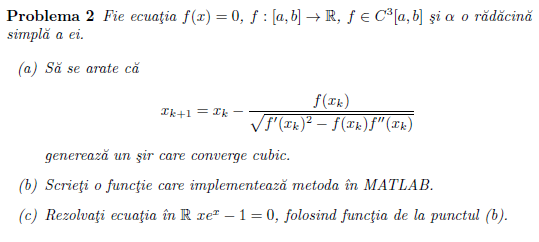

**a)**

 
$$\begin{array}{l}
\mathrm{Pentru}\;a\;\mathrm{obține}\;\mathrm{convergența}\;\mathrm{cubică}\;\left(\mathrm{adică}\;\mathrm{ordinul}\;\mathrm{de}\;\mathrm{convergență}\;p=3\right)\;\mathrm{trebuie}\;\mathrm{îndeplinite}\;\mathrm{următoarele}\;\mathrm{condiții}:\\
\mathrm{funcția}\;f\;\mathrm{se}\;\mathrm{anulează}\;\mathrm{în}\;\mathrm{rădăcina}\;\mathrm{aproximată}\;\alpha ,\mathrm{prima}\;\mathrm{derivată}\;a\;\mathrm{funcției}\;\mathrm{de}\;\mathrm{iterație}\;\phi \;\mathrm{trebuie}\;\mathrm{să}\;\mathrm{se}\;\mathrm{anuleze}\;\mathrm{în}\;\alpha ,\\
a\;\mathrm{doua}\;\mathrm{derivată}\;a\;\mathrm{funcției}\;\mathrm{de}\;\mathrm{iterație}\;\;\phi \;\mathrm{trebuie}\;\mathrm{să}\;\mathrm{se}\;\mathrm{anuleze}\;\mathrm{în}\;\alpha ,a\;\mathrm{treia}\;\mathrm{derivată}\;a\;\mathrm{funcției}\;\mathrm{de}\;\mathrm{iterație}\;\;\phi \;\mathrm{trebuie}\;\\
\mathrm{să}\;\mathrm{NU}\;\mathrm{se}\;\mathrm{anuleze}\;\mathrm{în}\;\alpha \ldotp \\
\mathrm{Scriem}\;\mathrm{sistemul}\;\mathrm{obținut}\;\mathrm{din}\;\mathrm{aceste}\;\mathrm{condiții}\;\mathrm{pentru}\;\mathrm{verificare}:f\left(\alpha \right)=0,\varphi^{\prime } \left(\alpha \right)=0,{\varphi^{\prime } }^{\prime } \left(\alpha \right)=0,{{\varphi^{\prime } }^{\prime } }^{\prime } \left(\alpha \right)\not= 0\ldotp 
\end{array}$$


syms x alpha lambda f(x) g(x)
phi = x - f(x)/(sqrt(diff(f(x), x, 1)^2-f*diff(f(x), x, 2)))

$$phi(x) = x-\frac{f\left(x\right)}{\sqrt{{\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}-f\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)}}$$


%am abordat aceste substituții deoarece matlab înlocuia și toate derivatele
%cu 0, nu doar funcția f la final
phi_prima_derivata = diff(phi, 1);
phi_prima_derivata = subs(phi_prima_derivata, ...
    [diff(f(x), x, 1), diff(f(x), x, 2), diff(f(x), x, 3)], ...
    [diff(g(x), x, 1), diff(g(x), x, 2), diff(g(x), x, 3)]);
phi_prima_derivata = simplify(subs(phi_prima_derivata, f, 0))

$$phi\_prima\_derivata(x) = 1-\frac{\frac{\partial }{\partial x}g\left(x\right)}{\sqrt{{\left(\frac{\partial }{\partial x}g\left(x\right)\right)}^{2}}}$$


$$\begin{array}{l}
\mathrm{Prima}\;\mathrm{derivată}\;a\;\mathrm{lui}\;\varphi \;\mathrm{este}\;\mathrm{într}-\mathrm{adevăr}\;0\;\left(a\;\mathrm{doua}\;\mathrm{parte}\;a\;\mathrm{diferenței}\;\mathrm{este}\;1,\mathrm{doar}\;\mathrm{nu}\;\mathrm{este}\;\mathrm{simplificat}\;\mathrm{în}\;\mathrm{MATLAB}\right)\ldotp \\
\mathrm{Continuăm}\;\mathrm{cu}\;a\;\mathrm{doua}\;\mathrm{derivată}:
\end{array}$$


phi_a_doua_derivata = diff(phi, 2);
phi_a_doua_derivata = subs(phi_a_doua_derivata, ...
    [diff(f(x), x, 1), diff(f(x), x, 2), diff(f(x), x, 3), diff(f(x), x, 4)], ...
    [diff(g(x), x, 1), diff(g(x), x, 2), diff(g(x), x, 3), diff(g(x), x, 4)]);
phi_a_doua_derivata = simplify(subs(phi_a_doua_derivata, f, 0))

$$phi\_a\_doua\_derivata(x) = 0$$


$$A\;\mathrm{doua}\;\mathrm{derivată}\;\mathrm{este}\;\mathrm{de}\;\mathrm{asemenea}\;0,\;\mathrm{continuăm}\;\mathrm{cu}\;a\;\mathrm{treia}\;\mathrm{derivată}\ldotp$$


phi_a_treia_derivata = diff(phi, 3);
phi_a_treia_derivata = subs(phi_a_treia_derivata, ...
    [diff(f(x), x, 1), diff(f(x), x, 2), diff(f(x), x, 3), diff(f(x), x, 4), diff(f(x), x, 5)], ...
    [diff(g(x), x, 1), diff(g(x), x, 2), diff(g(x), x, 3), diff(g(x), x, 4), diff(g(x), x, 5)]);
phi_a_treia_derivata = simplify(subs(phi_a_treia_derivata, f, 0))

$$phi\_a\_treia\_derivata(x) = \frac{\left(3\,{\left(\frac{\partial^{2}}{\partial x^{2}}g\left(x\right)\right)}^{2}-\frac{\partial^{3}}{\partial x^{3}}g\left(x\right)\,\frac{\partial }{\partial x}g\left(x\right)\,4\right)\,{\left(\frac{\partial }{\partial x}g\left(x\right)\right)}^{3}}{4\,{\left({\left(\frac{\partial }{\partial x}g\left(x\right)\right)}^{2}\right)}^{5/2}}$$


$$\mathrm{De}\;\mathrm{această}\;\mathrm{dată}\;\mathrm{derivata}\;\mathrm{nu}\;s-a\;\mathrm{mai}\;\mathrm{anulat},\mathrm{deci}\;\mathrm{șirul}\;\mathrm{converge}\;\mathrm{cubic}\ldotp$$


**b) **$\mathrm{Implementarea}\;\mathrm{funcției}\;\mathrm{este}\;\mathrm{mai}\;\mathrm{jos}\;\mathrm{în}\;\mathrm{fișier}\ldotp$

**c) **


$$\left.\mathrm{Definim}\;\mathrm{funcția},\;\mathrm{derivatele}\;\mathrm{de}\;\mathrm{ordinul}\;1\;\mathrm{și}\;2,\;\mathrm{apelăm}\;\mathrm{func}\mathrm{ția}\;\mathrm{scrisă}\;\mathrm{la}\;b\right):$$


syms x
%scriu si un g = f simbolic pentru grafic (altfel da warning)
g=x*exp(x) - 1;
f = @(x) x*exp(x) - 1;

fd = diff(f, x, 1)

$$fd = {\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x}$$

fd2 = diff(f, x, 2)

$$fd2 = 2\,{\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x}$$

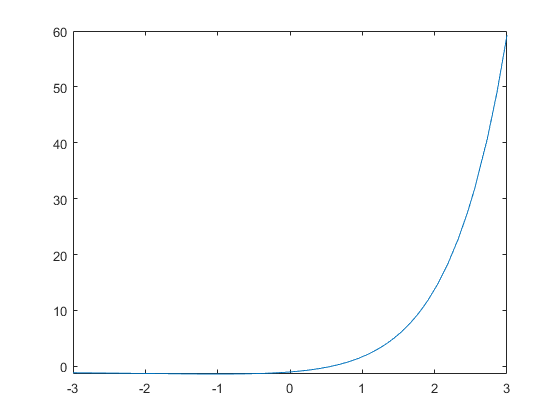


fplot(g,[-3,3])


$$\mathrm{Observăm}\;\mathrm{că}\;\mathrm{rădăcina}\;\mathrm{este}\;\mathrm{undeva}\;\mathrm{în}\;\mathrm{intervalul}\;\left\lbrack 0,2\right\rbrack ,\mathrm{deci}\;\mathrm{alegem}\;\mathrm{punct}\;\mathrm{de}\;\mathrm{pornire}\;\mathrm{ceva}\;\mathrm{aproape}\;\mathrm{de}\;\mathrm{aceasta}\ldotp \mathrm{Alegem}\;1\ldotp$$


[x_aprox, i] = newton_nou(f, fd, fd2, 1, 1e-5, 1e-10,100);
format long
x_aprox = eval(x_aprox)

x_aprox =    0.567143290409784



$$\mathrm{Comparăm}\;\mathrm{cu}\;\mathrm{valoarea}\;\mathrm{reală}\;\mathrm{pentru}\;a\;\mathrm{obține}\;\mathrm{eroarea}:$$


x_matlab = eval(solve(f(x)==0))

x_matlab =    0.567143290409784


eroare_real_aproximat = abs(x_aprox - x_matlab)

eroare_real_aproximat =      1.110223024625157e-16



$$\;$$


**FUNCȚII**

function rest = RR(f, a1, a2, a3, a4, t3, t4)
    syms t

    %partea integrala a restului
    rest = int(exp(-t)*f(t), t, 0, Inf) - a1*subs(f(t), t, 0) - ...
        a2*subs(diff(f(t), t), t, 0) - a3*f(t3) - a4*f(t4);
end

.

%[aproximare_radacina,nr_iteratii] -> output
function [z,ni]=newton_nou(f, fd, fd2, x0,ea,er,nmax)
    if nargin < 6, nmax=50; end
    if nargin < 5, er=0; end
    if nargin < 4, ea=1e-3; end
    xp=x0(:);
    for k=1:nmax
        xc=xp - f(xp)/sqrt(subs(fd, xp)^2 - f(xp)*subs(fd2, xp));
        if norm(xc-xp,inf)<ea+er*norm(xc,inf)
            z=xc; %succes
            ni=k;
            return
        end
        xp=xc;
    end
    error('S-a ajuns la nr. maxim de iteratii');
end

